# Satellite Image Processing - RGB

*Author: Avalon Royer*

*Student of Geography & Urban Planning at the Université Paris Cité.*

Satellite image processing plays an important role in land use observation and analysis as it allows for the coverage of vast areas, monitoring changes over time, and distinguishing different types of surfaces through multi-spectral data. It is particularly used for visualizing land use in hard-to-reach areas more easily, but also to support decision-making in urban planning, agriculture, and natural resource management, and to detect environmental changes such as deforestation or urbanization more quickly since it provides the ability to compare the same area at different time periods.

## Importing and Reading the Image

To read and display an image in MATLAB, use the `imshow` function after assigning the photo's title to a variable:

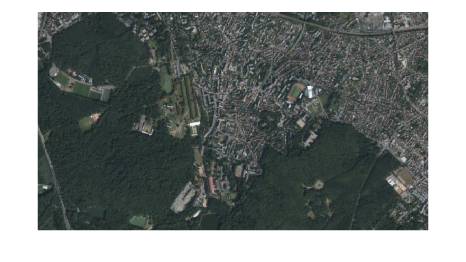

imageName="meudon_satellite.png";
I=imread(imageName);
imshow(imageName)

## Definition of Thresholds

The RGB (Red, Green, Blue) color model is a color representation system based on the principle of additive synthesis, in which various intensities of red, green and blue light are mixed to generate a palette of varied colors.

The image matrix therefore comprises 3 main colors, whose minimum and maximum thresholds must be chosen in order to define their intervals and thus highlight the color you wish to represent on the final production. To do this, simply move each slider to the desired value to select each min and max threshold for each color.

If, for example, you wish to represent the portion of territory covered by green vegetation, use the following max and min values:

redMin =20;
redMax =60;
greenMin =0;
greenMax =255;
blueMin =30;
blueMax =70;

## Conversion to Black & White Binary Mask 

With the following commands, we will isolate and visualize the parts of the image that fall within specific color ranges by creating a binary image mask based on these thresholds. We will obtain a binary mask (`sliderBW`) where the pixels within the specified ranges for the three color channels are set to true (1), and all other pixels are set to false (0). Next, we simply assign the created mask (`sliderBW`) to BW and then display the final image with `imshow`.

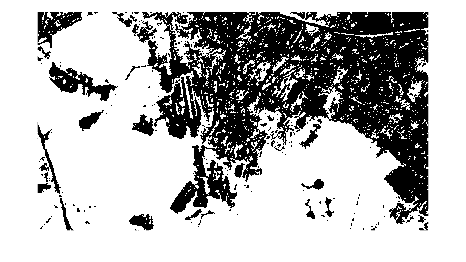

sliderBW = (I(:,:,1) >= redMin ) & (I(:,:,1) <= redMax) & ...
    (I(:,:,2) >= greenMin ) & (I(:,:,2) <= greenMax) & ...
    (I(:,:,3) >= blueMin ) & (I(:,:,3) <= blueMax);
BW = sliderBW;
imshow(BW)

## Final Segmentation 

We will isolate the black pixels to remove them from the image, segmenting it to leave only the part selected with the thresholds, in the RGB model.

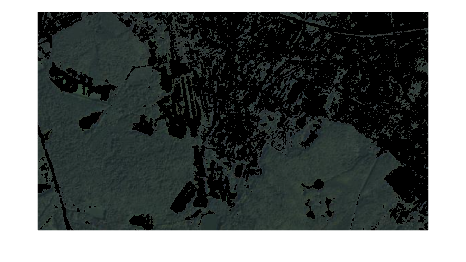

maskedRGBImage=I;
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;
imshow(maskedRGBImage)

## Calculate the Percentage of Vegetation Relative to Urbanized Areas 

Next, we want to calculate the representative percentage of the green vegetation area relative to the entire image selected for analysis. The ratio `sum(sum(BW))/(nbrow*nbcol)` gives the proportion of the image occupied by white pixels, representing the vegetation (prctVege).

[nbrow,nbcol]=size(BW);
prctVege = sum(sum(BW))/(nbrow*nbcol)

prctVege = 0.5864

*Image: Google Maps*